[sectn] = sectn_rectangularTube(a, b, t)

sectn_rectangularTube(a, b, t) computes the beam section properties for a beam of rectangular tube cross section.

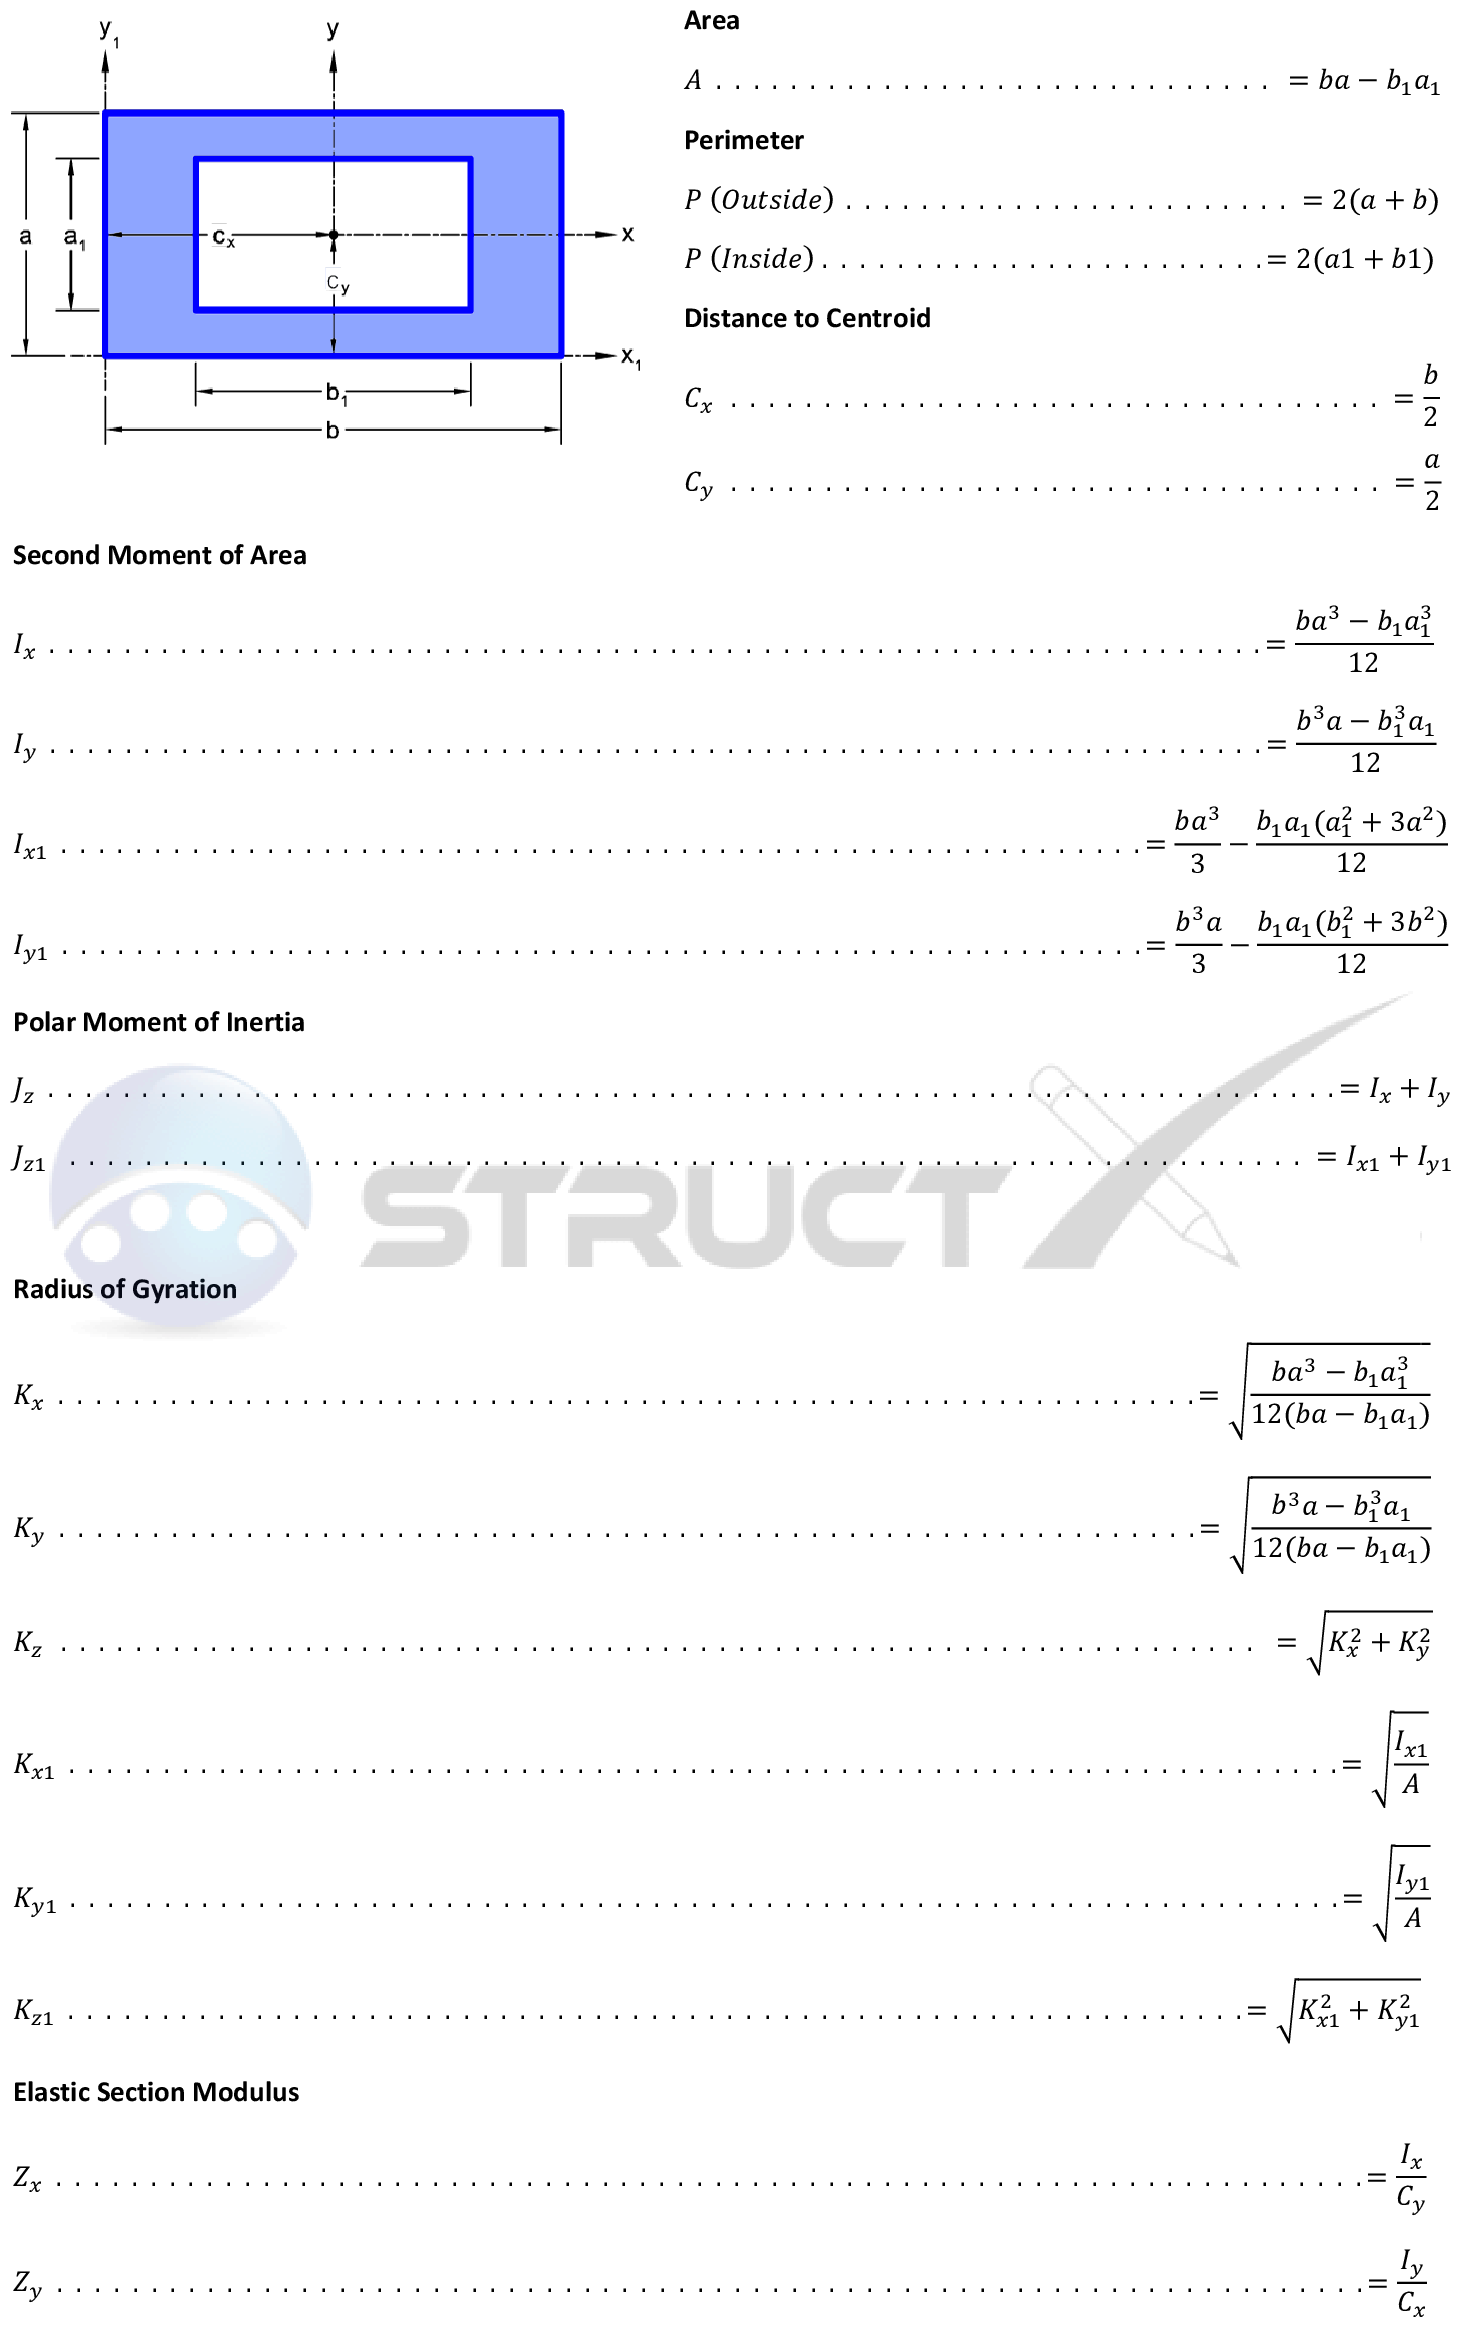

### Notation:

- A = Geometric Area, in2 or mm2

- C = Distance to Centroid, in or mm

- I = Second moment of area, in4 or mm4

- Ji = Polar Moment of Inertia, in4 or mm4, where i is x, y or z

- K = Radius of Gyration, in or mm

- P = Perimeter of shape, in or mm

- Z = Elastic Section Modulus, in3 or mm3

### Calling Sequence:

- [sectn] = sectn_rectangularTube(a, b, t)

#### Inputs:

- a - rectangle outside height

- b - rectangle outside base

- t - wall thickness

#### Outputs:

- sectn - sectn data structure with updated section properties

### Reference:

- https://structx.com/Shape_Formulas_023.html

function [sectn] = sectn_rectangularTube(a, b, t)
a1 = a-2*t;                             % height inside
b1 = b-2*t;                             % base inside
sectn.type = 'rectTube';                % section type
sectn.A = a*b - a1*b1;                  % cross-section area
sectn.P = 2*(a+b);                      % perimeter
sectn.C1 = a/2;                         % distance to centroid, axis-1
sectn.C2 = b/2;                         % distance to centroid, axis-2
sectn.I1 = (1/12)*(a^3*b - a1^3*b1);    % area moment of inertia, axis-1
sectn.I2 = (1/12)*(a*b^3 - a1*b1^3);    % area moment of inertia, axis-2
sectn.Jz = sectn.I1 + sectn.I2;         % polar moment of inertia
sectn.K1 = sqrt(sectn.I1/sectn.A);      % radius of gyration, axis-1
sectn.K2 = sqrt(sectn.I2/sectn.A);      % radius of gyration, axis-2
sectn.Z1 = sectn.I1/sectn.C1;           % section modulus, axis-1
sectn.Z2 = sectn.I2/sectn.C2;           % section modulus, axis-2
sectn.J  = a^3*b*((1/3)-((0.21-a)/b)*(1-(a^4/(12*b^4))));   % torsional constant
end